Aula 04

Resumo

Mancha de comentários no ficheiro de uma função externa

Matrizes

Gráfico de uma função (usando a função "plot") - exemplo com um polinómio

Matriz e tabela de resultados: exportar e importar dados (entre o MATLAB e o Excel)

clear

Mancha de comentários no ficheiro de uma função externa

% nome da função e descrição do objetivo da função
% descrição dos parâmetros de entrada (inputs)
% descrição dos parâmetros de saída (outputs)
% data e autor

Um pouco de matrizes

A = [1 2 3 ; 4 5 6]

A =      1     2     3
     4     5     6


A(2,2),A(1,3)

ans = 5

ans = 3

A(2,2)=7

A =      1     2     3
     4     7     6



c1 =[1 2],c2=[3 4]

c1 =      1     2


c2 =      3     4


c1.'%transposta

ans =      1
     2



%matriz transposta

[c1.' c2.']

ans =      1     3
     2     4


Gráfico de uma função usando a função "plot"

Exemplo com o polinómio $f(x)=x^2$

x = [-2 -1 0 1 2]; % vetor das abcissas dos pontos
y=[4 1 0 1 4]; %vetor das ordenadas
plot(x,y);
plot(x,y,"o");
plot(x,y,"-o");
plot(x,y,"-*r");

x = linspace(-2,2,20);
y=x.^2;
plot(x,y,"-*r");

Recorrendo às funções "polyval" e "MHorner" para calcular o vetor das ordenadas

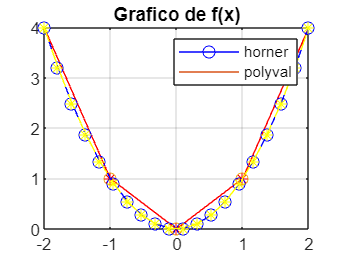

a = [0 0 1]; % vetor dos coeficientes do polinómio a = [a0 a1 a2]
x = linspace(-2,2,20);
yhorner=MHorner(a,x);
ypolival= polyval(flip(a),x);
plot(x,yhorner,"-ob")
hold on
plot(x,ypolival,"--*y");
hold off
title("Grafico de f(x)")
legend("horner", "polyval")
grid on

Exportar e importar dados (entre o MATLAB e o Excel)

Matriz ou Tabela de resultados

a = [0 0 2];
x = linspace(-2,2,20);
yhorner=MHorner(a,x);
ypolival= polyval(flip(a),x);

A = [x.' yhorner.' ypolival.']

A =    -2.0000    8.0000    8.0000
   -1.7895    6.4044    6.4044
   -1.5789    4.9861    4.9861
   -1.3684    3.7452    3.7452
   -1.1579    2.6814    2.6814
   -0.9474    1.7950    1.7950
   -0.7368    1.0859    1.0859
   -0.5263    0.5540    0.5540
   -0.3158    0.1994    0.1994
   -0.1053    0.0222    0.0222


% gravar matriz de dados num ficheiro
writematrix(A,"dadosM.xlsx")

% ler toda a informação de um ficheiro para uma matriz
readmatrix("dadosM.xlsx")

ans =    -2.0000    8.0000    8.0000
   -1.7895    6.4044    6.4044
   -1.5789    4.9861    4.9861
   -1.3684    3.7452    3.7452
   -1.1579    2.6814    2.6814
   -0.9474    1.7950    1.7950
   -0.7368    1.0859    1.0859
   -0.5263    0.5540    0.5540
   -0.3158    0.1994    0.1994
   -0.1053    0.0222    0.0222



% ler parte da informação de um ficheiro para uma matriz
readmatrix("dadosM.xlsx","Range","A3:C6")

ans =    -1.5789    4.9861    4.9861
   -1.3684    3.7452    3.7452
   -1.1579    2.6814    2.6814
   -0.9474    1.7950    1.7950


 
% converter uma matriz de dados numa tabela com nomes para as colunas
tabela = array2table(A,"VariableNames",["x","yHorner","yPolyval"])

tabela = 20×3 table
       x        yHorner     yPolyval
    ________    ________    ________

          -2           8           8
     -1.7895      6.4044      6.4044
     -1.5789      4.9861      4.9861
     -1.3684      3.7452      3.7452
     -1.1579      2.6814      2.6814
    -0.94737       1.795       1.795
    -0.73684      1.0859      1.0859
    -0.52632     0.55402     0.55402
    -0.31579     0.19945     0.19945
    -0.10526    0.022161    0.022161
     0.10526    0.022161    0.022161
     0.31579     0.19945     0.19945
     0.52632     0.55402     0.55402
     0.73684      1.0859      1.0859
     0.94737       1.795       1.795
      1.1579      2.6814      2.6814



% gravar tabela de dados num ficheiro
writetable(tabela,"dadosT.xlsx")

% ler toda a informação de um ficheiro para uma tabela


% ler parte da informação de um ficheiro para uma tabela
